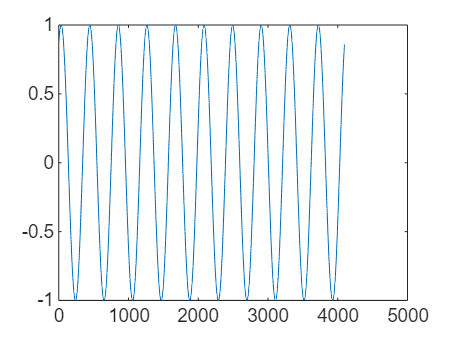

num = 3.94784176043574e9;
den = [1,8.8857534006821e4,3.94784176043574e9];
sys_filter = tf(num,den);

f_signal = 1e3;
fs = 409.6e3;
t = 0: 1/fs:20/f_signal;
signal = sin(2*pi*f_signal*t+pi/3);
singal2 = signal(1:4096);
plot(singal2);

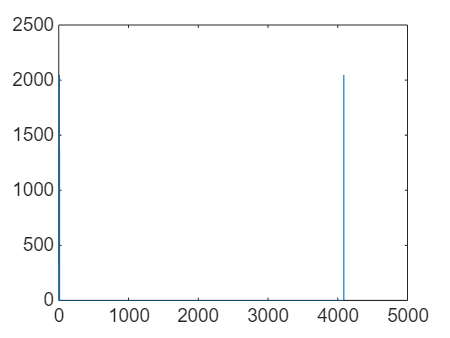

signalMag = abs(fft(singal2));
plot(signalMag);

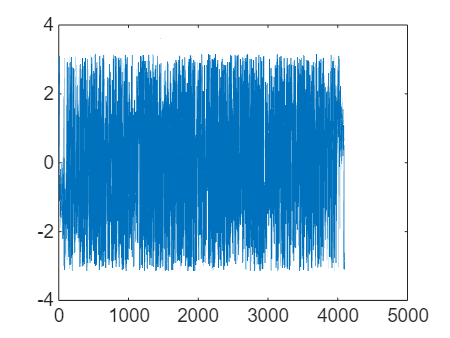

signalPha = angle(fft(singal2));
plot(signalPha);

ZOH = ones(1,5);
t = 0:1/1e3:20/1e3;
signal1 = sin(2*pi*100*t);